# Projekt 5

## Nastavitev parametrov

% Definicija parametrov
T = 0.01;
N = 300;
N_APRBS = 3000;
amplitude_train = 2.5;
amplitude_test = 2.0;
Th = 0.20;
padding = 100;
dV = 0.05;
c = zeros(2 / dV + 1, 1);

## Statična karaktersitika

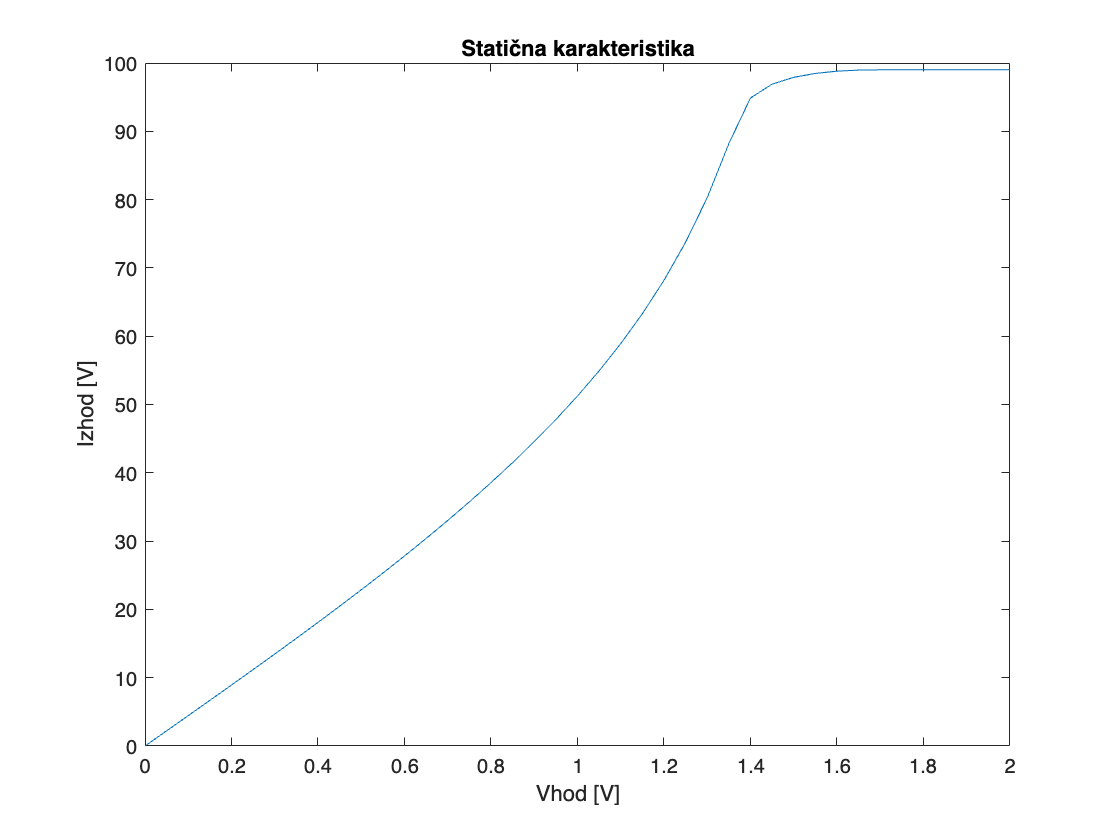

% Zanka za različne vrednosti V
for V = 0:dV:2
    u = ones(N, 1) * V;

    % Inicializacija stanja
    x = [0, 0];

    % Inicializacija izhodnega vektorja
    y = zeros(N, 1);

    % Simulacija helicrana
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u(i), x);

        % Posodobitev stanja
        x = [fip_, fi_];

        % Shranjevanje izhoda
        y(i) = fi_;
    end

    % Izračun povprečja izhodnih vrednosti po prehodnem obdobju
    y_m = mean(y(100:end));

    % Shranjevanje rezultata v c
    c(round(V/dV) + 1) = y_m;
end

% Risanje rezultata
figure;
plot(0:dV:2, c);
title("Statična karakteristika");
xlabel("Vhod [V]");
ylabel("Izhod [V]");

## Generiranje in risanje APRBS signala

% Parametri
N = 1000; % Število vzorcev
Th = 5; % Časovna konstanta
T = 0.1; % Čas vzorčenja
amplitude_train = 2.5;
amplitude_test = 2.5;
padding = 100;
N_APRBS = N; % Število APRBS vzorcev

% Generiranje APRBS signala za treniranje
u_train = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

d_train = diff(u_train);
idx_train = find(d_train) + 1;
idx_train = [1; idx_train];
for ii = 1:length(idx_train) - 1
    u_train(idx_train(ii):idx_train(ii + 1) - 1) = amplitude_train * rand;
end
u_train(idx_train(end):end) = amplitude_train * rand;
u_train = [zeros(padding, 1); u_train];
u_train = u_train - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri testu more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Generiranje APRBS signala za testiranje
u_test = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

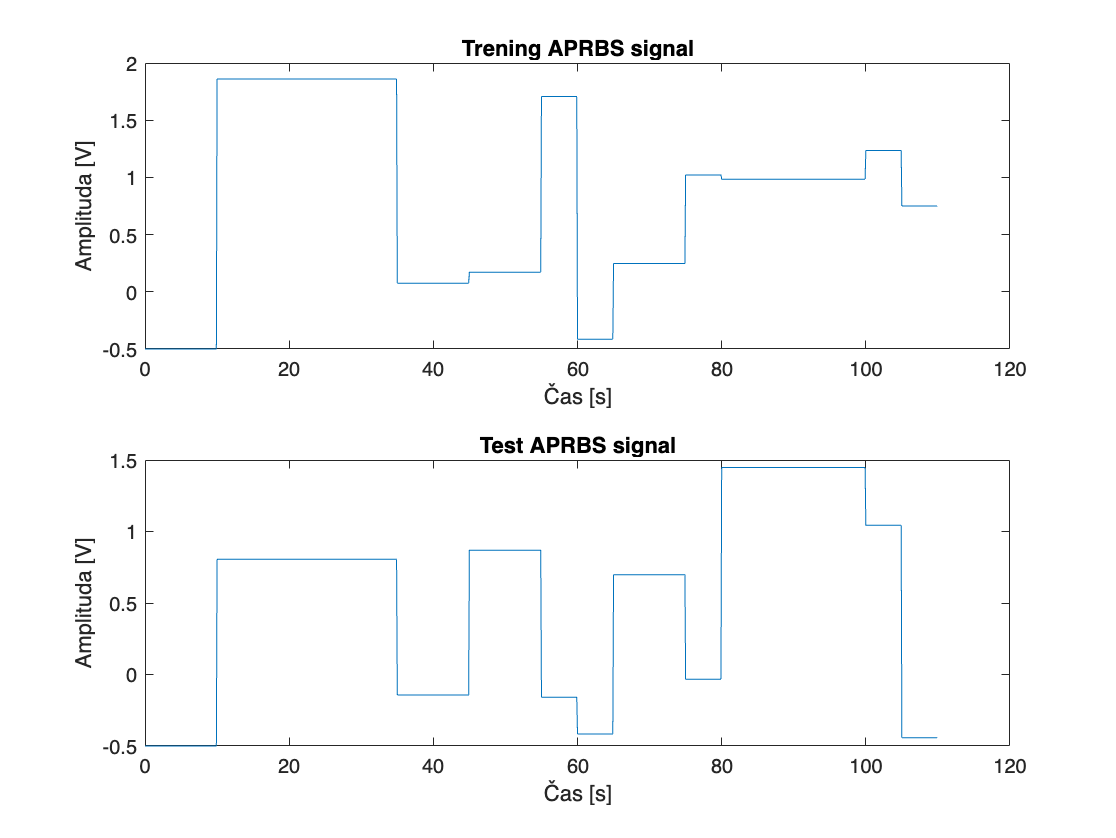

d_test = diff(u_test);
idx_test = find(d_test) + 1;
idx_test = [1; idx_test];
for ii = 1:length(idx_test) - 1
    u_test(idx_test(ii):idx_test(ii + 1) - 1) = amplitude_test * rand;
end
u_test(idx_test(end):end) = amplitude_test * rand;
u_test = [zeros(padding, 1); u_test];
u_test = u_test - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri train more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Časovni vektorji
t_train = (0:length(u_train)-1) * T;
t_test = (0:length(u_test)-1) * T;

% Risanje rezultatov
figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Trening APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

## odziv sistema na vhodni signal

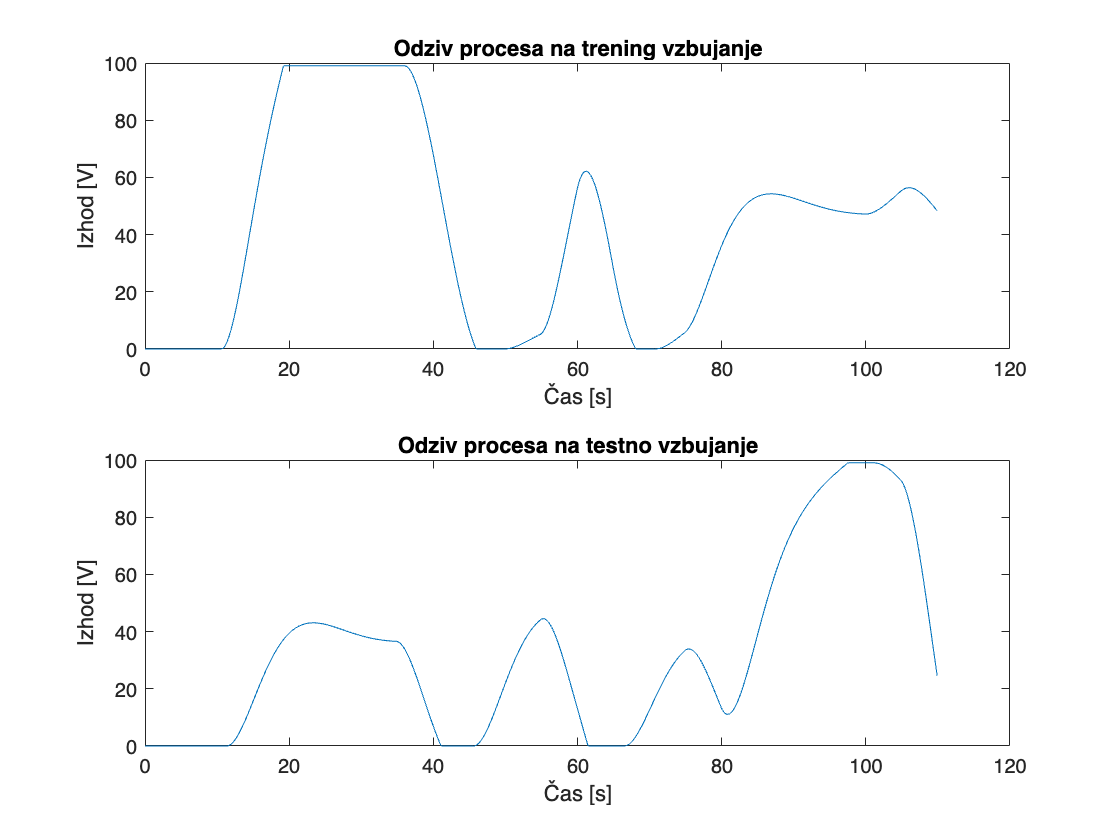


% Simulacija odziva sistema za treniranje in testiranje
y_train = simulate_helicrane(u_train, [0 0]);
y_test = simulate_helicrane(u_test, [0 0]);

% Risanje rezultatov simulacije
figure
subplot(2, 1, 1);
plot(t_train, y_train);
title("Odziv procesa na trening vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

subplot(2, 1, 2);
plot(t_test, y_test);
title("Odziv procesa na testno vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");


% Preverjanje dolžine vektorjev u_train in y_train
if length(u_train) > 2 && length(y_train) > 2
    % Priprava vhodnih in izhodnih podatkov za učenje
    X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
    Y_train_podatki = y_train(3:end);

    % Premešanje podatkov za učenje
    perm_indeksi = randperm(size(X_train_podatki, 1));
    X_train_premesani = X_train_podatki(perm_indeksi, :);
    Y_train_premesani = Y_train_podatki(perm_indeksi, :);

    % Priprava vhodnih in izhodnih podatkov za testiranje
    X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
    Y_test_podatki = y_test(3:end);

    % Simulacija helicrana brez uporabe funkcije
    % Inicializacija stanja
    zacetno_stanje = [0, 0];

    % Dolžina vhoda
    N = length(u_train); % Tu mora biti dolžina u_train

    % Inicializacija izhoda
    izhodi = zeros(N, 1);

    % Glavna zanka za simulacijo
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u_train(i), zacetno_stanje);

        % Posodobitev stanja
        zacetno_stanje = [fip_, fi_];

        % Shranjevanje izhoda
        izhodi(i) = fi_;
    end

    % Prikaz končnih izhodov (izhodi)
    disp(izhodi);
else
    disp('Napaka: u_train ali y_train nimata dovolj elementov.');
end

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0

## nevronska mreža

net = feedforwardnet([15, 12, 10]);
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'poslin';
net.trainParam.showWindow = false;
net.trainParam.goal = 2e-6;
[net, ~] = train(net, X_train_podatki', Y_train_podatki');

% Napovedovanje na trening množici
Y_pred_train = net(X_train_podatki');

% Napovedovanje na testni množici
Y_pred_test = net(X_test_podatki');

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
title("Modeliranje trening množice z NN");
hold on;
plot(Y_pred_train);
xlabel("Vzorec");
ylabel("Odziv [V]");

subplot(2, 1, 2);
plot(Y_test_podatki);
title("Modeliranje testne množice z NN");
hold on;
plot(Y_pred_test);
xlabel("Vzorec");
ylabel("Odziv [V]");


## Takagi Sugeno model

% 1) Priprava vhodnih podatkov (X_train) in izhodnih podatkov (Y_train)
X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
Y_train_podatki = y_train(3:end);


[X_train_podatki, mu_X_train, sigma_X_train] = normalize(X_train_podatki);
[Y_train_podatki, mu_Y_train, sigma_Y_train] = normalize(Y_train_podatki);

% Inicializacija parametrov
R = 11; % Število pravil
[C, U] = fcm(X_train_podatki, R); % K-means za centre funkcij pripadnosti

Iteration count = 1, obj. fcn = 529.493
Iteration count = 2, obj. fcn = 397.586
Iteration count = 3, obj. fcn = 389.284
Iteration count = 4, obj. fcn = 356.148
Iteration count = 5, obj. fcn = 298.735
Iteration count = 6, obj. fcn = 243.136
Iteration count = 7, obj. fcn = 186.88
Iteration count = 8, obj. fcn = 136.818
Iteration count = 9, obj. fcn = 109.3
Iteration count = 10, obj. fcn = 102.363
Iteration count = 11, obj. fcn = 97.221
Iteration count = 12, obj. fcn = 92.4142
Iteration count = 13, obj. fcn = 87.3076
Iteration count = 14, obj. fcn = 82.2695
Iteration count = 15, obj. fcn = 78.1963
Iteration count = 16, obj. fcn = 75.1376
Iteration count = 17, obj. fcn = 72.9194
Iteration count = 18, obj. fcn = 71.1764
Iteration count = 19, obj. fcn = 69.3777
Iteration count = 20, obj. fcn = 67.0528
Iteration count = 21, obj. fcn = 64.0691
Iteration count = 22, obj. fcn = 60.678
Iteration count = 23, obj. fcn = 57.3323
Iteration count = 24, obj. fcn = 54.7301
Iteration count = 25, obj. fcn

O = ones(R, 1) * std(X_train_podatki); % Širine funkcij pripadnosti
W = rand(R, size(X_train_podatki, 2)) * 2 - 1; % Uteži
b = rand(R, 1) * 2 - 1; % Pragovi

% Parametri treniranja
alpha_initial = 0.001;  % Začetna hitrost učenja
alpha_decay = 0.99;     % Zmanjšanje hitrosti učenja
epochs = 1000;          % Število epoh

% Treniranje TS modela
for epoch = 1:epochs
    alpha = alpha_initial * (alpha_decay ^ epoch);
    e_avg = 0;
    for j = 1:size(X_train_podatki, 1)
        [C, O, W, b, e] = TS_train_single(C, O, W, b, X_train_podatki(j, :)', Y_train_podatki(j), alpha);
        e_avg = e_avg + e;
    end
    e_avg = e_avg / size(X_train_podatki, 1);
    
    if mod(epoch, 100) == 0
        fprintf("Epoka %d: Povprečna napaka: %f\n", epoch, e_avg);
    end
end

Epoka 100: Povprečna napaka: 0.003651
Epoka 200: Povprečna napaka: 0.002926
Epoka 300: Povprečna napaka: 0.002751
Epoka 400: Povprečna napaka: 0.002693
Epoka 500: Povprečna napaka: 0.002673
Epoka 600: Povprečna napaka: 0.002666
Epoka 700: Povprečna napaka: 0.002663
Epoka 800: Povprečna napaka: 0.002663
Epoka 900: Povprečna napaka: 0.002662
Epoka 1000: Povprečna napaka: 0.002662


fprintf("Končna povprečna napaka: %f\n", e_avg);

Končna povprečna napaka: 0.002662


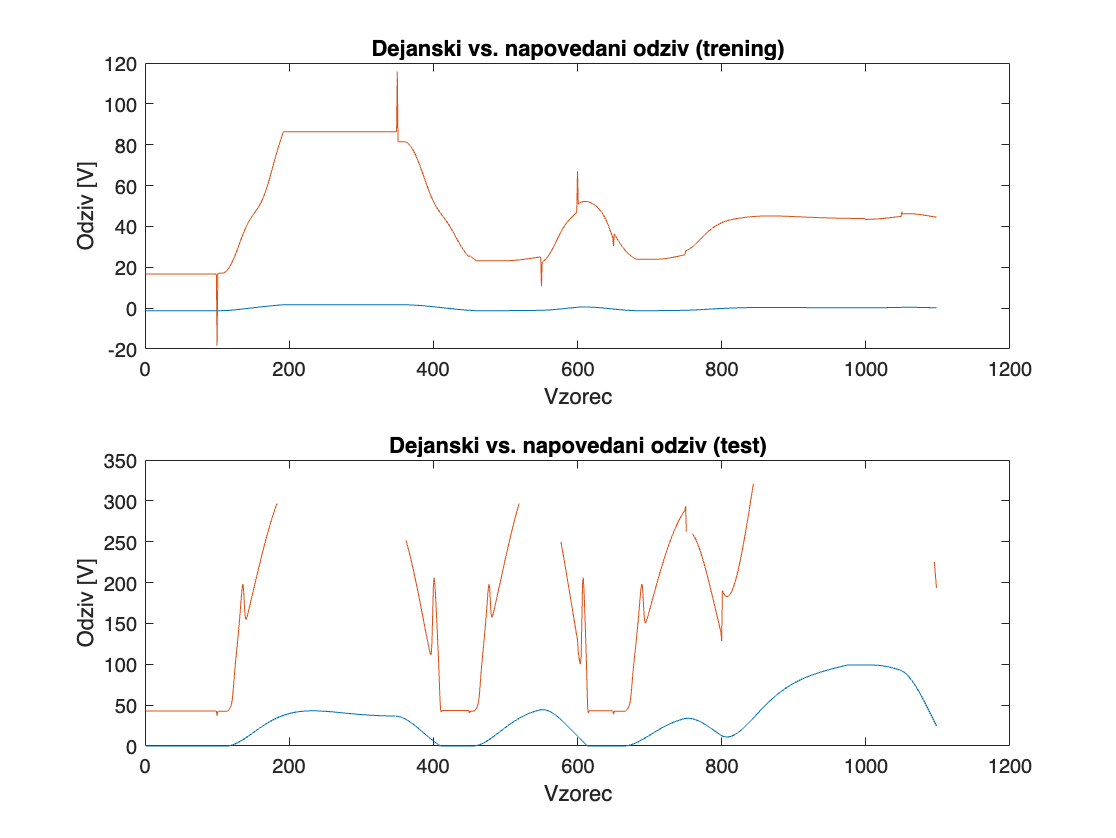


% Testiranje na testnih podatkih
Y_pred_train = TS_eval(C, O, W, b, X_train_podatki');
Y_pred_test = TS_eval(C, O, W, b, X_test_podatki');

% Denormalizacija napovedi
Y_pred_train = Y_pred_train * sigma_Y_train + mu_Y_train;
Y_pred_test = Y_pred_test * sigma_Y_train + mu_Y_train;

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
hold on;
plot(Y_pred_train);
title('Dejanski vs. napovedani odziv (trening)');
xlabel('Vzorec');
ylabel('Odziv [V]');

subplot(2, 1, 2);
plot(Y_test_podatki);
hold on;
plot(Y_pred_test);
title('Dejanski vs. napovedani odziv (test)');
xlabel('Vzorec');
ylabel('Odziv [V]');

function [C, O , W, b, e] = TS_train_single(C, O, W, b, X, Y, alpha)
    % X je zdaj celoten vektor, dimenzij 4x1, kar ustreza podatkovnemu vektorju
    
    mu = exp(-0.5 * sum((X' - C).^2 ./ (O.^2), 2)); % mu - stolpčni vektor
    if sum(mu) < 0.001
        mu = mu / sum(mu); % Normalizacija pripadnosti
    end
    
    s = W * X + b; % Sledi izračunu napovedi modela
    y = sum(mu .* s);
    
    % Izračun gradientov glede na parametre
    dmu_dC = (X' - C) ./ (O.^2) .* mu;
    dmu_dO = (X' - C).^2 ./ (O.^3) .* mu;
    
    dy_dC = dmu_dC .* (s - sum(s .* mu)) ./ (sum(mu).^2);
    dy_dO = dmu_dO .* (s - sum(s .* mu)) ./ (sum(mu).^2);
    
    dy_db = mu;
    dy_dW = mu * X';
    
    % Izračun napake
    e = (Y - y).^2;
    
    % Posodobitev parametrov
    de_dC = -2 * (Y - y) * dy_dC;
    de_dO = -2 * (Y - y) * dy_dO;
    
    de_db = -2 * (Y - y) * dy_db;
    de_dW = -2 * (Y - y) * dy_dW;
    
    C = C - alpha .* de_dC;
    O = O - alpha .* de_dO;
    b = b - alpha .* de_db;
    W = W - alpha .* de_dW;
end
function [Y] = TS_eval(C, O, W, b, X)
    N = size(X, 2);
    Y = zeros(1, N);
    for i = 1:N
        mu = exp(-0.5 * sum((X(:, i)' - C).^2 ./ (O.^2), 2)); % Uporabite celoten vektor X
        mu = mu / sum(mu); % Normalizacija pripadnosti
        
        s = W * X(:, i) + b;
        Y(i) = sum(mu .* s);
    end
end
